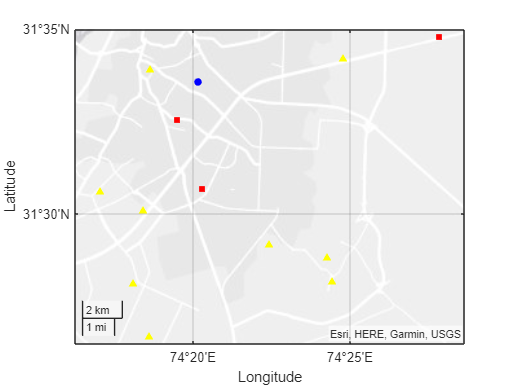

%task1

Locations = readtable("Locations.csv");
ID = Locations{:,1}';
lat = Locations{:,2};
long = Locations{:,3};

la = lat(2:10);
lon = long(2:10);

A = la;
C = lon;

geoscatter(la,lon,A,C, "filled",'^', 'yellow')
hold on;

lati = lat(11:13);
longi = long(11:13);

B = lati;
D = longi;
geoscatter(lati,longi,B,D,'filled', 'square', 'red')

hold on;

lati = lat(1:1);
longi = long(1:1);

E = lati;
F = longi;
geoscatter(lati,longi,E,F,"filled",'o', 'blue')
hold off

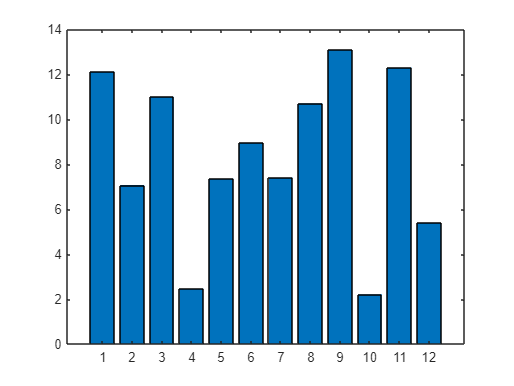

%task2
R = 6371;
count = 0;
Formula = [];
for index = 1:length(ID)
    lat1 = lat(index)*pi/180;
    long1 = long(index)*pi/180;
    for idx = index+1:13
        lat2 = lat(idx)*pi/180;
        long2 = long(idx)*pi/180;
        change_lat = (lat1-lat2);
        change_long = (long1 - long2);
        a = sin((change_lat)/2).^2 + cos(lat1) * cos(lat2) * (sin(change_long)/2).^2;
        c = 2 * atan2( sqrt(a), sqrt((1-a)) );
        Formula(end+1) = R * c;
    end
end
US = Formula(1,1:12);
distance = 1:1:12;
bar(US)

%Task 3
x = readtable("AirQualityData.csv");
US = x{944:1114,2}';
RankeLUMS = x{944:1114,3}';
PairGardenTown = x{944:1114,4}';
PairDhaPhase2 = x{944:1114,5}';
PairAnarkali = x{944:1114,6}';
PairHarbanspura = x{944:1114,7}';
PairDefenceChowk = x{944:1114,8}';
PairIqbalTown = x{944:1114,9}';
PairAkbarChowk = x{944:1114,10}';
PairTownship = x{944:1114,11}';
MetStation = x{944:1114,12}';
DentalCollege = x{944:1114,13}';
EPAGulberg = x{944:1114,14}';

correlations = [];
correlation1 = corellation_function(US,RankeLUMS);
correlations(end+1) = correlation1(1,2);

correlation2 = corellation_function(US,PairGardenTown);
correlations(end+1) = correlation2(1,2);

correlation3 = corellation_function(US,PairDhaPhase2);
correlations(end+1) = correlation3(1,2);

correlation4 = corellation_function(US,PairAnarkali);
correlations(end+1) = correlation4(1,2);

correlation5 = corellation_function(US,PairHarbanspura);
correlations(end+1)= correlation5(1,2);

correlation6 = corellation_function(US,PairDefenceChowk);
correlations(end+1) = correlation6(1,2);

correlation7 = corellation_function(US,PairIqbalTown);
correlations(end+1) = correlation7(1,2);

correlation8 = corellation_function(US,PairAkbarChowk);
correlations(end+1) = correlation8(1,2);

correlation9 = corellation_function(US,PairTownship);
correlations(end+1) = correlation9(1,2);

correlation10 = corellation_function(US,MetStation);
correlations(end+1) = correlation10(1,2);

correlation11 = corellation_function(US,DentalCollege);
correlations(end+1) = correlation11(1,2);

correlation12 = corellation_function(US,EPAGulberg);
correlations(end+1)= correlation12(1,2);

% correlations
corr = correlations(1,1:12)

corr =     0.9436    0.9857    0.9698    0.9626    0.9632    0.9812    0.9852    0.9551    0.9691       NaN       NaN    0.7509


distance = 1:1:12

distance =      1     2     3     4     5     6     7     8     9    10    11    12


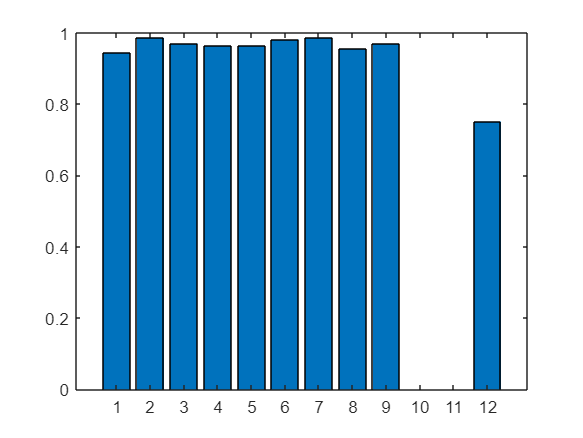

bar(corr)

MetStation and Dental College give outputs as NaN which means that the correlation between these two with respect to the USEmbassy is negative. This is due to the fact that the two variables consistently move in opposite directions to one another. 

%Task 4

p = polyfit(RankeLUMS,US,1);
RenkeLUMSReading = (p(1,1).*US ) + p(1,2);
RenkeLUMSReadingCalibrated = (RenkeLUMSReading-p(1,2))/p(1,1)

RenkeLUMSReadingCalibrated =    92.8750   37.1250   84.5833   43.9167   52.7917   -1.0000   -1.0000   -1.0000   -1.0000   -1.0000   62.7917   -1.0000   -1.0000   74.0000   54.3333   65.5833   63.7083   65.1250   60.1250   62.2500   47.8333   35.4167   70.8333   68.7917   64.6667   76.0417   66.1250   60.1667   61.7917   63.6250   52.5833   -1.0000   -1.0000   -1.0000   -1.0000   -1.0000   -1.0000   -1.0000   -1.0000   -1.0000   45.7500   58.4583   58.6667   81.5417   62.1667   92.0000   47.8333   25.3333   42.8333   56.4167



p = polyfit(PairGardenTown,US,1);
PairGardenTownReading = (p(1,1).*US )+ p(1,2);
GardenTownCalibrated = (PairGardenTownReading-p(1,2))/p(1,1)

GardenTownCalibrated =    92.8750   37.1250   84.5833   43.9167   52.7917   -1.0000   -1.0000   -1.0000   -1.0000   -1.0000   62.7917   -1.0000   -1.0000   74.0000   54.3333   65.5833   63.7083   65.1250   60.1250   62.2500   47.8333   35.4167   70.8333   68.7917   64.6667   76.0417   66.1250   60.1667   61.7917   63.6250   52.5833   -1.0000   -1.0000   -1.0000   -1.0000   -1.0000   -1.0000   -1.0000   -1.0000   -1.0000   45.7500   58.4583   58.6667   81.5417   62.1667   92.0000   47.8333   25.3333   42.8333   56.4167



p = polyfit(PairDhaPhase2,US,1);
PairDhaPhase2Reading = (p(1,1).*US )+ p(1,2);
PairDhaPhase2Calibrated = (PairDhaPhase2-p(1,2))/p(1,1)

PairDhaPhase2Calibrated = 	1.0e+03 *

   -0.1658   -0.1658   -0.1658   -0.1658   -0.1658   -0.1658    0.0229    0.0143   -0.0157   -0.0209   -0.0247   -0.0478   -0.0164   -0.0420   -0.1658   -0.1658   -0.0027   -0.1658   -0.0366   -0.0304   -0.1658   -0.0583   -0.0315    0.0419   -0.0021   -0.0364   -0.0513   -0.0579   -0.0398    0.0019   -0.0413   -0.0433    0.0259   -0.0180   -0.0182    0.0266    0.0113    0.0171   -0.0372   -0.0504   -0.0493   -0.0866   -0.0740    0.0023   -0.0475   -0.0143   -0.0265   -0.0870   -0.0189    0.0076



p = polyfit(PairAnarkali,US,1);
PairAnarkaliReading = (p(1,1).*US )+ p(1,2);
PairAnarkaliCalibrated = (PairAnarkaliReading-p(1,2))/p(1,1)

PairAnarkaliCalibrated =    92.8750   37.1250   84.5833   43.9167   52.7917   -1.0000   -1.0000   -1.0000   -1.0000   -1.0000   62.7917   -1.0000   -1.0000   74.0000   54.3333   65.5833   63.7083   65.1250   60.1250   62.2500   47.8333   35.4167   70.8333   68.7917   64.6667   76.0417   66.1250   60.1667   61.7917   63.6250   52.5833   -1.0000   -1.0000   -1.0000   -1.0000   -1.0000   -1.0000   -1.0000   -1.0000   -1.0000   45.7500   58.4583   58.6667   81.5417   62.1667   92.0000   47.8333   25.3333   42.8333   56.4167



p = polyfit(PairHarbanspura,US,1);
PairHarbanspuraReading = (p(1,1).*US )+ p(1,2);
PairHarbanspuraCalibrated = (PairHarbanspuraReading-p(1,2))/p(1,1)

PairHarbanspuraCalibrated =    92.8750   37.1250   84.5833   43.9167   52.7917   -1.0000   -1.0000   -1.0000   -1.0000   -1.0000   62.7917   -1.0000   -1.0000   74.0000   54.3333   65.5833   63.7083   65.1250   60.1250   62.2500   47.8333   35.4167   70.8333   68.7917   64.6667   76.0417   66.1250   60.1667   61.7917   63.6250   52.5833   -1.0000   -1.0000   -1.0000   -1.0000   -1.0000   -1.0000   -1.0000   -1.0000   -1.0000   45.7500   58.4583   58.6667   81.5417   62.1667   92.0000   47.8333   25.3333   42.8333   56.4167



p = polyfit(PairDefenceChowk,US,1);
PairDefenceChowkReading = (p(1,1).*US )+ p(1,2);
PairDefenceChowkCalibrated = (PairDefenceChowkReading-p(1,2))/p(1,1)

PairDefenceChowkCalibrated =    92.8750   37.1250   84.5833   43.9167   52.7917   -1.0000   -1.0000   -1.0000   -1.0000   -1.0000   62.7917   -1.0000   -1.0000   74.0000   54.3333   65.5833   63.7083   65.1250   60.1250   62.2500   47.8333   35.4167   70.8333   68.7917   64.6667   76.0417   66.1250   60.1667   61.7917   63.6250   52.5833   -1.0000   -1.0000   -1.0000   -1.0000   -1.0000   -1.0000   -1.0000   -1.0000   -1.0000   45.7500   58.4583   58.6667   81.5417   62.1667   92.0000   47.8333   25.3333   42.8333   56.4167



p = polyfit(PairIqbalTown,US,1);
PairIqbalTownReading = (p(1,1).*US )+ p(1,2);
PairIqbalTownCalibrated = (PairIqbalTownReading-p(1,2))/p(1,1)

PairIqbalTownCalibrated =    92.8750   37.1250   84.5833   43.9167   52.7917   -1.0000   -1.0000   -1.0000   -1.0000   -1.0000   62.7917   -1.0000   -1.0000   74.0000   54.3333   65.5833   63.7083   65.1250   60.1250   62.2500   47.8333   35.4167   70.8333   68.7917   64.6667   76.0417   66.1250   60.1667   61.7917   63.6250   52.5833   -1.0000   -1.0000   -1.0000   -1.0000   -1.0000   -1.0000   -1.0000   -1.0000   -1.0000   45.7500   58.4583   58.6667   81.5417   62.1667   92.0000   47.8333   25.3333   42.8333   56.4167



p = polyfit(PairAkbarChowk,US,1);
PairAkbarChowkReading = (p(1,1).*US )+ p(1,2);
PairAkbarChowkCalibrated = (PairAkbarChowkReading-p(1,2))/p(1,1)

PairAkbarChowkCalibrated =    92.8750   37.1250   84.5833   43.9167   52.7917   -1.0000   -1.0000   -1.0000   -1.0000   -1.0000   62.7917   -1.0000   -1.0000   74.0000   54.3333   65.5833   63.7083   65.1250   60.1250   62.2500   47.8333   35.4167   70.8333   68.7917   64.6667   76.0417   66.1250   60.1667   61.7917   63.6250   52.5833   -1.0000   -1.0000   -1.0000   -1.0000   -1.0000   -1.0000   -1.0000   -1.0000   -1.0000   45.7500   58.4583   58.6667   81.5417   62.1667   92.0000   47.8333   25.3333   42.8333   56.4167



p = polyfit(PairTownship,US,1);
PairTownshipReading = (p(1,1).*US )+ p(1,2);
PairTownshipCalibrated = (PairTownshipReading-p(1,2))/p(1,1)

PairTownshipCalibrated =    92.8750   37.1250   84.5833   43.9167   52.7917   -1.0000   -1.0000   -1.0000   -1.0000   -1.0000   62.7917   -1.0000   -1.0000   74.0000   54.3333   65.5833   63.7083   65.1250   60.1250   62.2500   47.8333   35.4167   70.8333   68.7917   64.6667   76.0417   66.1250   60.1667   61.7917   63.6250   52.5833   -1.0000   -1.0000   -1.0000   -1.0000   -1.0000   -1.0000   -1.0000   -1.0000   -1.0000   45.7500   58.4583   58.6667   81.5417   62.1667   92.0000   47.8333   25.3333   42.8333   56.4167


%Task5
%lums started with 1090
x = readtable("AirQualityData.csv");

us = x{2:1116,2}';
us_refined = us;
us_refined(us==-1)=0

us_refined =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0



GardenTown = x{2:1116,4}';
GardenTown_refined = GardenTown;
GardenTown_refined(GardenTown==-1)=0

GardenTown_refined =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0



DhaPhase2 = x{2:1116,5}';
DhaPhase2_refined = DhaPhase2;
DhaPhase2_refined(DhaPhase2==-1)=0

DhaPhase2_refined =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0



Anarkali = x{2:1116,6}'

Anarkali =     -1    -1    -1    -1    -1    -1    -1    -1    -1    -1    -1    -1    -1    -1    -1    -1    -1    -1    -1    -1    -1    -1    -1    -1    -1    -1    -1    -1    -1    -1    -1    -1    -1    -1    -1    -1    -1    -1    -1    -1    -1    -1    -1    -1    -1    -1    -1    -1    -1    -1


Anarkali_refined = Anarkali;
Anarkali_refined(Anarkali==-1)=0

Anarkali_refined =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0



Harbanspura = x{2:1116,7}';
Harbanspura_refined = Harbanspura;
Harbanspura_refined(Harbanspura==-1)=0

Harbanspura_refined =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0



DefenceChowk = x{2:1116,8}';
DefenceChowk_refined = DefenceChowk;
DefenceChowk_refined(DefenceChowk==-1)=0

DefenceChowk_refined =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0



IqbalTown = x{2:1116,9}';
IqbalTown_refined = IqbalTown;
IqbalTown_refined(IqbalTown==-1)=0

IqbalTown_refined =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0



AkbarChowk = x{2:1116,10}';
AkbarChowk_refined= AkbarChowk;
AkbarChowk_refined(AkbarChowk==-1)=0

AkbarChowk_refined =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0



Township = x{2:1116,11}';
Township_refined= Township;
Township_refined(Township==-1)=0

Township_refined =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0



MetSta = x{2:1116,12}';
MetSta_refined = MetSta;
MetSta_refined(MetSta==-1)=0

MetSta_refined =   111.8310   63.4870  113.9010   90.3800   62.7320   93.5950   90.0260   72.2580   82.3360   99.0260   76.4490   31.9840   37.4620   70.9890   67.1980   91.0030   63.1530   57.1660   36.7930   30.3250   24.3820   45.2010   79.8510   64.3740   77.8730   52.0230   55.6920   44.9140   39.4590   15.2810   26.1230   26.5330   29.8920   30.1260   17.5450    8.4000         0         0         0         0   31.6830   96.5450   51.3060  103.2760  123.0860  105.1200   88.4740   45.2840   70.1240   72.6930



Dental = x{2:1116,13}';
Dental_refined=Dental;
Dental_refined(Dental==-1)=0

Dental_refined =   446.3130  257.0090         0         0         0  175.1680  209.2850  201.8190  208.4040  212.7820   76.4490   72.1220   99.7530  217.4390  274.7570  277.0760  232.1960  231.8680  201.2360   85.7150   45.8050   67.3710  155.7540  196.0620  163.8620  319.0680  257.7430  134.6760  261.9080   63.2820   70.4350  134.9490  220.8170  216.4860  212.3250  124.7290   61.5100   53.4590  109.6340  148.3330  197.8390  244.7960   51.3060  103.2760   85.4110  144.4110  138.6670   50.4240   56.0280   72.6930



EPAG = x{2:1116,14}';
EPAG_refined=EPAG;
EPAG_refined(EPAG==-1)=0

EPAG_refined =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


function correlation = corellation_function(US_values,comparison_values)
    Refined_US_Data = US_values;
    Refined_comparison_Data = comparison_values;
    Refined_US_Data(comparison_values ==-1 | US_values ==-1)=[];
    Refined_comparison_Data(comparison_values ==-1 | US_values ==-1)=[];
    correlation = corrcoef(Refined_US_Data,Refined_comparison_Data);
end